load("Data\CFD_confined_TSR_1_1.mat")
X = flow_data(1).X;
Y = flow_data(1).Y;
theta = zeros(length(flow_data),1);
for i = 1:length(flow_data)
    theta(i) = flow_data(i).theta;
end
%thetab = flip(theta);
thetab = 365 - theta;
syms t
Ry2 = [cosd(t) sind(t); -sind(t) cosd(t)];


k = 1

k = 1

alpha = theta(k);
U = flow_data(k).u;
V = flow_data(k).v;
sz = length(X)

sz = 100

Xrot3 = zeros(sz);
Yrot3 = zeros(sz);
tic
for j = 1:sz
    T3 = [X(:,1)';Y(:,j)'];
    XYRy2 = Ry2*T3; 
    res = subs(XYRy2,t,alpha);
    Xrot3(:,j) = res(1,:);
    Yrot3(:,j) = res(2,:);
end
toc

Elapsed time is 13.186612 seconds.


foiltest = plot_foil(theta(k),1);
XYRy2 = Ry2*foiltest';
res = subs(XYRy2,t,alpha);
foiltest(:,:) = res';

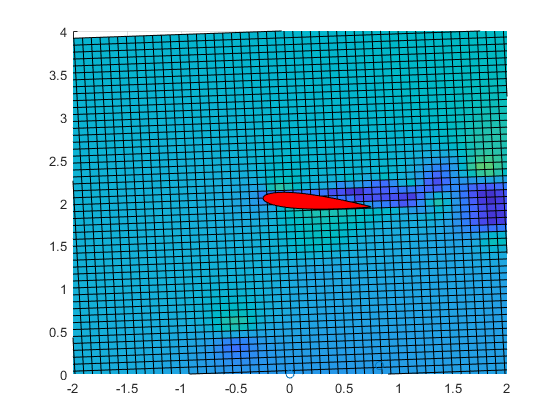

surf(Xrot3,Yrot3,U)
view([0 90])
hold on
Z = ones(length(foiltest),1)*25;
fill3(foiltest(:,1),foiltest(:,2),Z,'r')
xlim([-2 2])
ylim([0 4])
plot3([0;Umean],[0;Vmean],[25 25],'o')
hold off

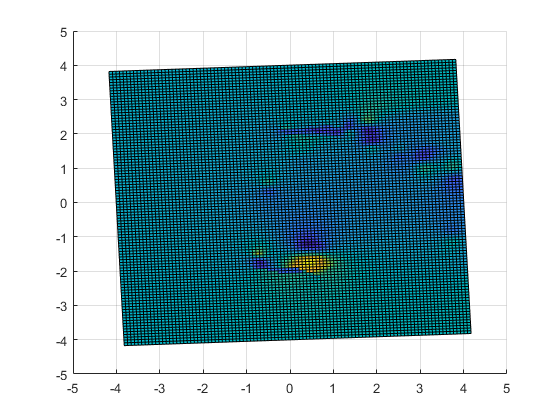

surf(Xrot3,Yrot3,U)
view([0 90])

thet = [0:pi/32:2*pi,0]';
%qc = 2.118*[cosd(theta(k));sind(theta(k))]
qc = 2.118*[sind(theta(k));cosd(theta(k))]

qc =    -0.0935
    2.1159


qc = Ry2*qc;
qc = subs(qc,t,-alpha);
qc = double(qc)

qc =    -0.0000
    2.1180


xi = qc(1);
yi = qc(2);
r = 1;
xv = r*cos(thet)+xi;
yv = r*sin(thet)+yi;
in = inpolygon(Xrot3,Yrot3,xv,yv);
sum(sum(in))

ans = 480

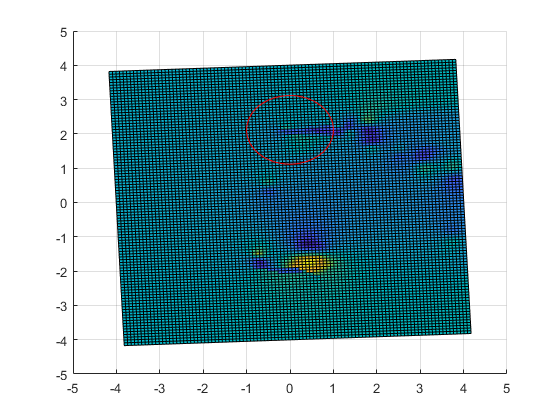

surf(Xrot3,Yrot3,U)
view([0 90])
hold on
Z = ones(length(xv))*25;
plot3(xv,yv,Z,'r')
hold off

Umean = mean(U(in))

Umean = 0.8192

Vmean = mean(V(in))

Vmean = 0.1059

Vect = [0 Umean;0 Vmean]

Vect =          0    0.8192
         0    0.1059


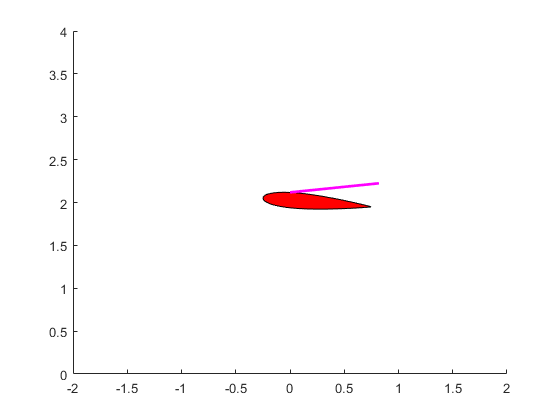

Z = ones(length(foiltest),1)*25;
fill3(foiltest(:,1),foiltest(:,2),Z,'r')
view([0 90])
hold on
xlim([-2 2])
ylim([0 4])
plot3([qc(1);Umean+qc(1)],[qc(2);Vmean+qc(2)],[25 25],'m','LineWidth',2)
hold off

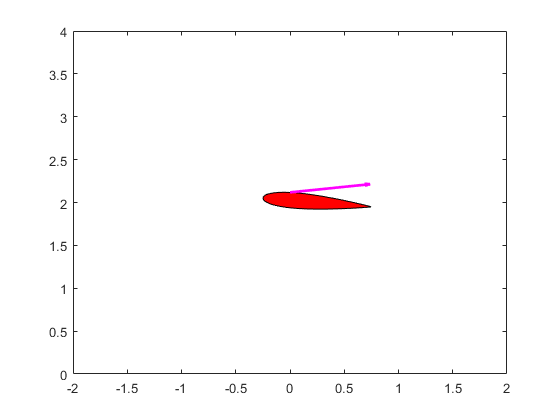

fill(foiltest(:,1),foiltest(:,2),'r')
xlim([-2 2])
ylim([0 4])
hold on
quiver(qc(1),qc(2),Umean,Vmean,'m','LineWidth',2)
hold off

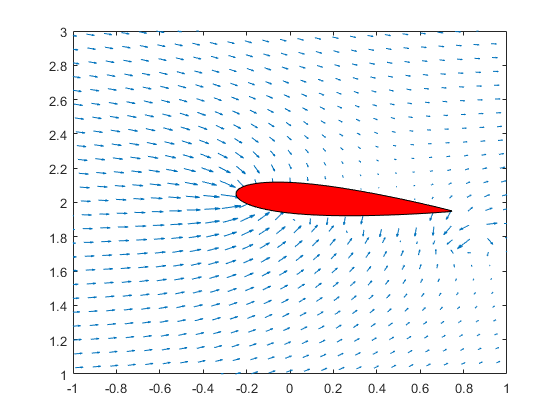

quiver(Xrot3,Yrot3,U,V)
xlim([-1 1])
ylim([1 3])
hold on
fill(foiltest(:,1),foiltest(:,2),'r')

quiver(0,2.059,Umean,Vmean,'m','LineWidth',2)
hold off
